% VERNIER SCALE READING VS WAVELENGTH

yFunc = @(x, xdata) x(1).*xdata + x(2);

% HELIUM
% actual data
Y = [7.41 8.76 11.4 11.82 12.89 14.46];
wavelength = [667.8 587.6 501.6 492.2 471.3 447.1];
inv_wavelength = 1./(wavelength-286);
y_err = [0.005 0.005 0.005 0.005 0.005 0.005];
x_err = [0 0 0 0 0 0];

% fitting shit
x0 = [20, 20];
mb = lsqcurvefit(yFunc, x0, inv_wavelength, Y)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


mb = 	1.0e+03 *

    1.9710    0.0022


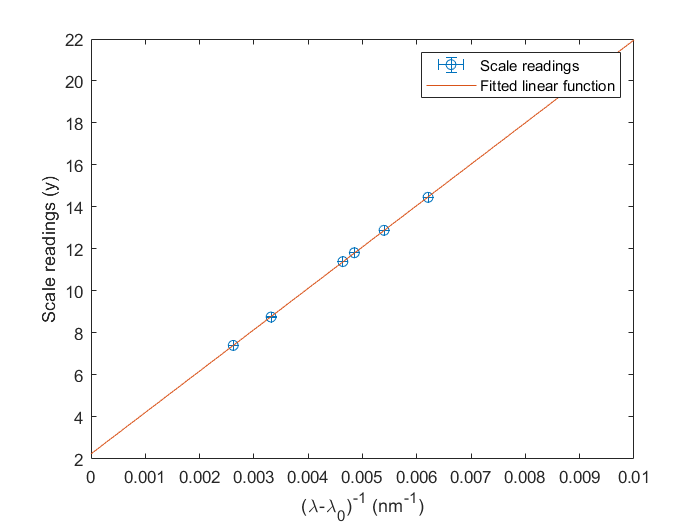


% fitted function
inv_wavelength_fit = [0:0 0.01];
y_fit = yFunc(mb, inv_wavelength_fit);

errorbar(inv_wavelength, Y, y_err, y_err, x_err, x_err, 'o');
hold on
plot(inv_wavelength_fit, y_fit);
% title('Scale reading (y) vs. (\lambda-\lambda_0)^{-1} for Helium');
legend('Scale readings', 'Fitted linear function');
xlabel('(\lambda-\lambda_0)^{-1} (nm^{-1})');
ylabel('Scale readings (y)');
hold off



% HYDROGEN
% actual data
Y = [7.53 12.13 14.55 15.5];
wavelength = [656.3 486.1 434 410.2];
inv_wavelength = 1./(wavelength-286);
y_err = [0.005 0.005 0.005 0.005];
x_err = [0 0 0 0];

% fitting shit
x0 = [20, 20];
mb = lsqcurvefit(yFunc, x0, inv_wavelength, Y)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


mb = 	1.0e+03 *

    1.5120    0.0039


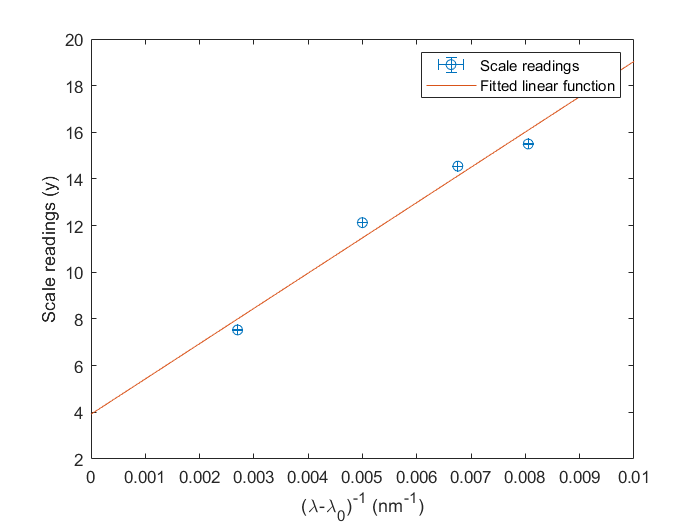


% fitted function
inv_wavelength_fit = [0:0 0.01];
y_fit = yFunc(mb, inv_wavelength_fit);

errorbar(inv_wavelength, Y, y_err, y_err, x_err, x_err, 'o');
hold on
plot(inv_wavelength_fit, y_fit);
% title('Scale reading (y) vs. (\lambda-\lambda_0)^{-1} for Hydrogen');
legend('Scale readings', 'Fitted linear function');
xlabel('(\lambda-\lambda_0)^{-1} (nm^{-1})');
ylabel('Scale readings (y)');
hold off



% BOTH
% actual data
Y = [7.41 8.76 11.4 11.82 12.89 14.46 7.53 12.13 14.55 15.5];
wavelength = [667.8 587.6 501.6 492.2 471.3 447.1 656.3 486.1 434 410.2];
inv_wavelength = 1./(wavelength-286);
y_err = [0.005 0.005 0.005 0.005 0.005 0.005 0.005 0.005 0.005 0.005];
x_err = [0 0 0 0 0 0 0 0 0 0];

% fitting shit
x0 = [20, 20];
mb = lsqcurvefit(yFunc, x0, inv_wavelength, Y)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


mb = 	1.0e+03 *

    1.6188    0.0036


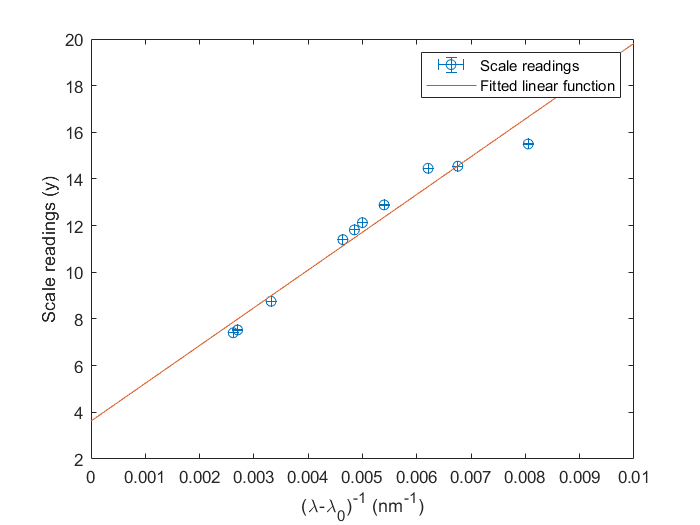


% fitted function
inv_wavelength_fit = [0:0 0.01];
y_fit = yFunc(mb, inv_wavelength_fit);

errorbar(inv_wavelength, Y, y_err, y_err, x_err, x_err, 'o');
hold on
plot(inv_wavelength_fit, y_fit);
% title('Scale reading (y) vs. (\lambda-\lambda_0)^{-1}');
legend('Scale readings', 'Fitted linear function');
xlabel('(\lambda-\lambda_0)^{-1} (nm^{-1})');
ylabel('Scale readings (y)');
hold off

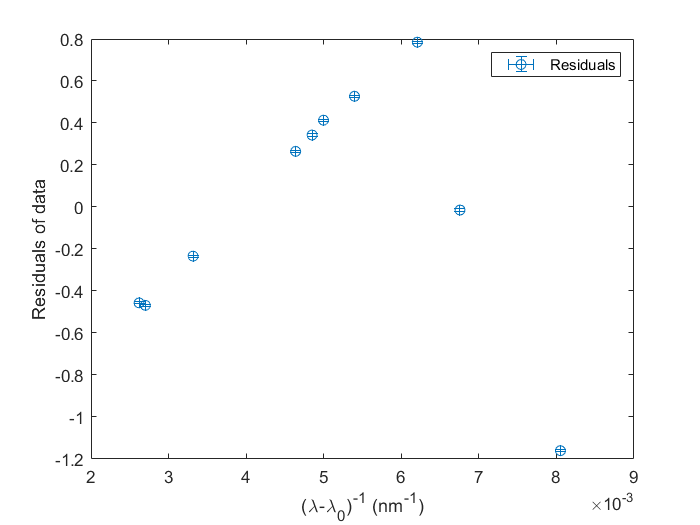


% RESIDUALS
Y = [7.41 8.76 11.4 11.82 12.89 14.46 7.53 12.13 14.55 15.5];
wavelength = [667.8 587.6 501.6 492.2 471.3 447.1 656.3 486.1 434 410.2];
inv_wavelength = 1./(wavelength-286);
y_fit = yFunc(mb, inv_wavelength);
zero = [0 0 0 0 0 0 0 0 0 0];
residuals = Y - y_fit;
errorbar(inv_wavelength, residuals, y_err, y_err, x_err, x_err, 'o');
% title('Residuals');
legend('Residuals');
xlabel('(\lambda-\lambda_0)^{-1} (nm^{-1})');
ylabel('Residuals of data');
hold off

% plot(inv_wavelength, zero);